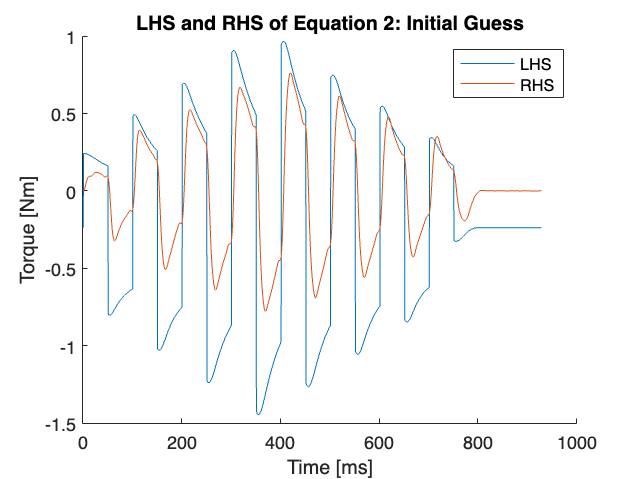

csvFileName = '4671B.csv'; 
dataTable = readtable(csvFileName); 
dataTable = dataTable(6:end-1,:);

pitch = 0.02;


sg = 0.887; % A/v 
kt = 0.72; % Nm/A 
Je = 5.9054E-4;
% name | enc1 pos | enc2 pos | enc 1 vel | enc 2 vel | V sig 

time = table2array(dataTable(:,"Var1"));
enc1_pos = table2array(dataTable(:, "Var2"));
enc2_pos = table2array(dataTable(:, "Var3")); 
enc1_vel = table2array(dataTable(:, "Var4")); 
vin = table2array(dataTable(:, "Var6")); 
%plot(time,enc1_pos)

%angular_vel = enc1_pos*10^-3 / pitch * 2 * pi;

angular_vel = enc1_vel * 10^-3 / pitch * 2 * pi; 

Ts = 0.5/1000;
[B,A]=butter(4,100*2*Ts);
filtered = filtfilt(B,A,angular_vel);

angular_accel1 = deriv(filtered, Ts);
clf
%plot(time(1:end-1), angular_accel1)
%plot(time, angular_vel)

hold on
title('LHS and RHS of Equation 2: Initial Guess')
LHS = sg*kt*vin - 0.0105 * angular_vel - 0.238; 
RHS = Je * angular_accel1; 
plot(time, LHS)
plot(time,RHS)
xlabel('Time [ms]')
ylabel('Torque [Nm]')
legend("LHS","RHS")
saveas(gcf, "Equation2FirstAttempt.png")

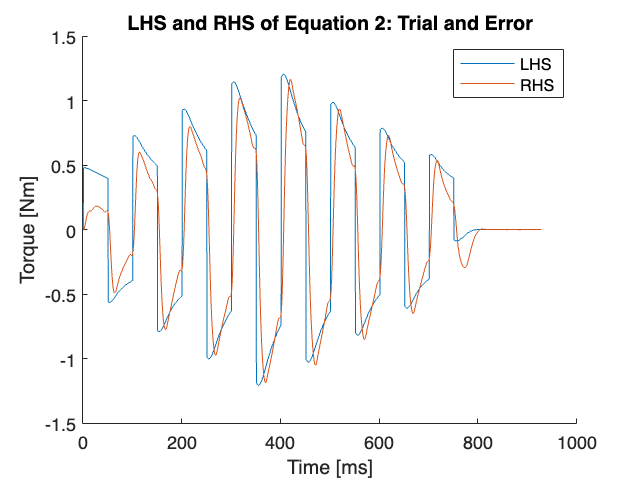


clf
Je = 9E-4; 
hold on
title('LHS and RHS of Equation 2: Trial and Error')
LHS = sg*kt*vin - 0.0105 * angular_vel ; % I REMOVED THE TD TERM BECAUSE OFFSET
RHS = Je * angular_accel1; 
plot(time, LHS)
plot(time,RHS)
xlabel('Time [ms]')
ylabel('Torque [Nm]')
legend("LHS","RHS")
saveas(gcf, "Equation2TrialError.png")